# EMAT30007 Applied Statistics

# Worksheet 6: Linear Models (Multiple Linear Regression)

## Nikolai Bode

This worksheet has two parts. In the first part, you will work through a multiple linear regression example including model selection. The second half is a collection of exercises on model selection.

## (1) Multiple Linear Regression Example

In this part of the worksheet we'll work through an example in some detail. We will use one of the data sets we already encountered in the last worksheet, but we will consider more variables as possible predictors. As a reminder, the data was collected to investigate the energy use of appliances in low-energy buildings. The data set is from one house. Readings were taken every 10 minutes for about 4.5 months. Reference for the data:

[Candanedo, L. M., Feldheim, V., Deramaix, D. (2017) "Data driven prediction models of energy use of appliances in a low-energy house". Energy and Buildings, Volume 140, 1 April 2017, Pages 81-97]

You can find the data in the file 'APPLIANCES2.csv'.

In this file, the response 'Appliances' is included alongside four variables that have been measured independently of the energy usage of the appliances (outside temperature, pressure outside, humidity outside, windspeed outside). The task is to establish which out of these variables (if any) help to predict the energy usage of the appliances in the house.

***1.1 Preliminary analysis***

It is always a good idea to have a look at the raw data to see if this shows some trends. Read in the data and plot scatterplots of the possible predictors against the energy usage of appliances.

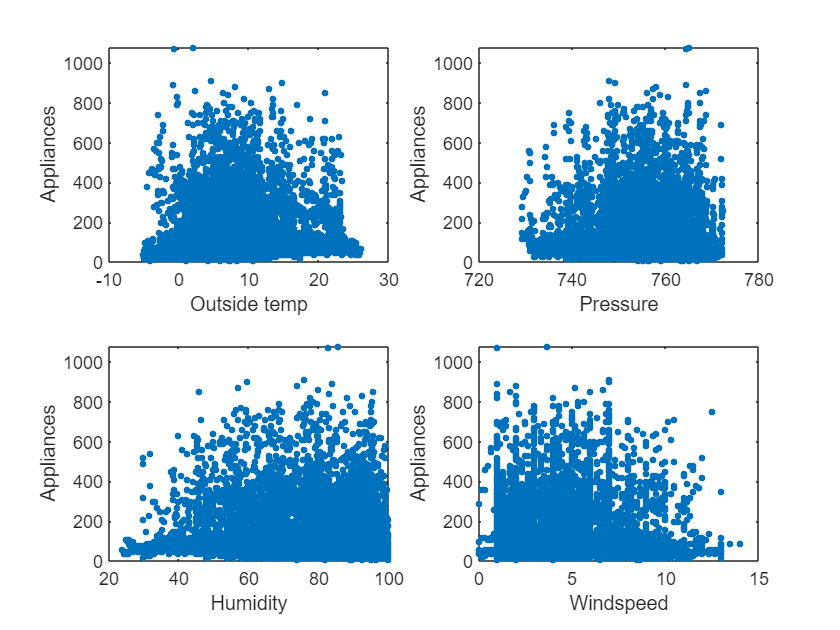

data = readtable("APPLIANCES2.csv");

appliances = data.Appliances;
temps = data.Temperature_outside_celsius;
pressure =data.Pressure_outside_mm_hg;
humidity = data.Humidity_outside_percent;
windspeed = data.Windspeed_meters_per_second;

%% plot scatterplots
clf
subplot(2,2,1)
plot(temps,appliances,'.', 'MarkerSize',10)
ylabel('Appliances') % x-axis label
xlabel('Outside temp') % y-axis label

subplot(2,2,2)
plot(pressure,appliances,'.', 'MarkerSize',10)
ylabel('Appliances') % x-axis label
xlabel('Pressure') % y-axis label

subplot(2,2,3)
plot(humidity,appliances,'.', 'MarkerSize',10)
ylabel('Appliances') % x-axis label
xlabel('Humidity') % y-axis label

subplot(2,2,4)
plot(windspeed,appliances,'.', 'MarkerSize',10)
ylabel('Appliances') % x-axis label
xlabel('Windspeed') % y-axis label

With this many data points, it can be hard to tell what's going on in plots of raw data. So we proceed to statistical analysis using a multiple linear regression model.

***1.2. Multiple linear regression***

When performing statistical model fitting on data that includes more than one possible predictor, there are different approaches. We could either start with minimal models that only consider one predictor at a time or we could fit a full model that includes all available predictors. Either approach is valid and which one to use typically depends on the type of analysis. For an exploratory analysis as we perform it here, it is often convenient to start with a full model.

Fit a full model to the data. The code in Matlab for multiple linear regression is a straighforward extension of what we do for simple linear regression. In `fitlm()`, simply add more predictors to the model, separating them with a '+'.

vars = 'Appliances~Temperature_outside_celsius+Pressure_outside_mm_hg+Humidity_outside_percent+Windspeed_meters_per_second';
m1 = fitlm(data, vars)

m1 = Linear regression model:
    Appliances ~ 1 + Temperature_outside_celsius + Pressure_outside_mm_hg + Humidity_outside_percent + Windspeed_meters_per_second

Estimated Coefficients:
                                    Estimate        SE         tStat        pValue  
                                   __________    ________    _________    __________

    (Intercept)                        545.65      80.196        6.804    1.0468e-11
    Temperature_outside_celsius    -0.0052315     0.17051    -0.030681       0.97552
    Pressure_outside_mm_hg           -0.49835     0.10358      -4.8114    1.5102e-06
    Humidity_outside_percent          -1.0074    0.060943       -16.53    5.7247e-61
    Windspeed_meters_per_second         2.212     0.30902        7.158    8.4738e-

This model fit tells us quite a few things already. Consider r-squared. This is quite low (you should find `R-squared=0.0281`), suggesting that only a small proportion of the variance in the responce (appliance energy usage) is explained by the model. However, the F-test suggests that our model is better than a constant model (i.e. one that only includes the intercept, `p-value=1.56e-120`). The t-tests are specific to the parameters linked with the different variables. Before we consider these in more detail, look at the residual plots for this model fit (use the same plots as in worksheet 5).

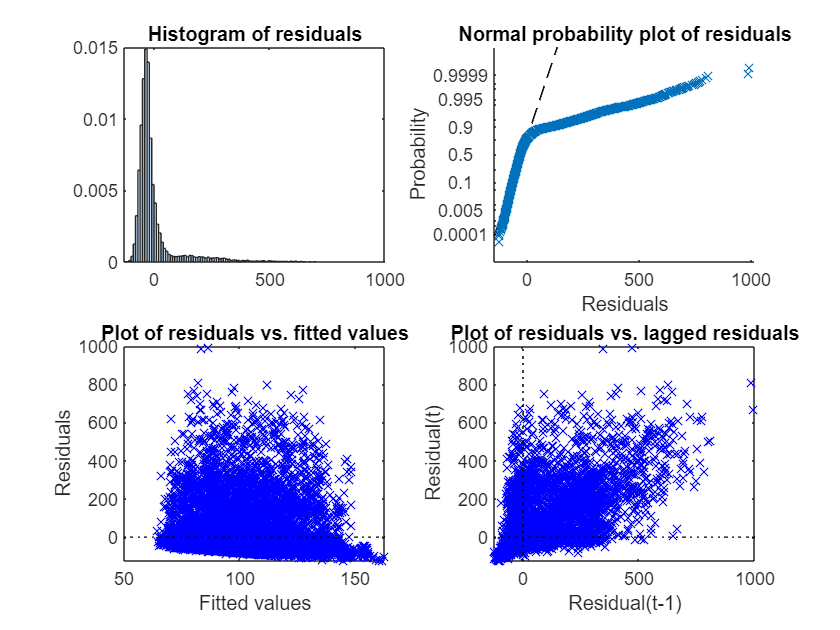

% plot distribution of residuals (for outliers etc.)
clf
subplot(2,2,1)
plotResiduals(m1)
% plot to check normality
subplot(2,2,2)
plotResiduals(m1,'probability')
% residuals versus fitted values (check for homoscedasticity)
subplot(2,2,3)
plotResiduals(m1,'fitted')
% auto-correlation (via lagged residuals)
subplot(2,2,4)
plotResiduals(m1,'lagged') % want no trend in this!

These plots look pretty catastrophic - very similar to what we saw in worksheet 5. Really, at this stage, we should reconsider fundamental aspects of our modelling approach or seek additional variables that might explain the features we see in the data.

However, to illustrate model selection, we will continue with this type of model for the data.

***1.3. Model selection***

Have another look at the table produced by the model fit above. Remember that the t-tests investigate the null hypothesis that the parameter associated with a variable in the regression model equals zero. For temperature it looks like we cannot reject the null hypothesis (interesting, considering that in worksheet 5 temperature had an effect...!!!).

So let's fit a new model to the data that does not include the predictor temperature.

vars = 'Appliances~Pressure_outside_mm_hg+Humidity_outside_percent+Windspeed_meters_per_second';
m2 = fitlm(data, vars)

m2 = Linear regression model:
    Appliances ~ 1 + Pressure_outside_mm_hg + Humidity_outside_percent + Windspeed_meters_per_second

Estimated Coefficients:
                                   Estimate       SE        tStat       pValue  
                                   ________    ________    _______    __________

    (Intercept)                         545      77.327      7.048    1.8753e-12
    Pressure_outside_mm_hg         -0.49765     0.10103    -4.9255     8.481e-07
    Humidity_outside_percent        -1.0063    0.049543    -20.312     8.552e-91
    Windspeed_meters_per_second      2.2114     0.30854     7.1675    7.9072e-13


Number of observations: 19735, Error degrees of freedom: 19731
Root Mean Squared Error: 101
R-squared: 0.0281,  Adjusted R-Squared: 0.028
F-statistic v

We can now assess in two ways whether this model is an improvement compared to the full model we fitted earlier.

First, we can compare quality measures like the AIC or BIC for the models (remember, lower values are better and also recall my dislike of r-squared for model comparison!). You can find quality measures for a fitted model 'm' in Matlab using the command 'm.ModelCriterion'.

m1.ModelCriterion

ans = struct with fields:
     AIC: 2.3820e+05
    AICc: 2.3820e+05
     BIC: 2.3824e+05
    CAIC: 2.3825e+05


m2.ModelCriterion

ans = struct with fields:
     AIC: 2.3820e+05
    AICc: 2.3820e+05
     BIC: 2.3823e+05
    CAIC: 2.3824e+05


The AIC and certainly the BIC should be somewhat smaller for the reduced model we fitted.

Second, we can use a Likelihood-ratio test, to formally test the null hypothesis that the parameter associated with temperature is equal to zero (notice how this tests something similar to the t-test, but it requires another model to be fitted).

In Matlab, the command is `lratiotest(logL_full, logL_reduced, df)`, where `logL_full` and `logL_reduced` are the log-likelihood for the full and reduced model, respectively (access these for a model `m` with the command `m.LogLikelihood`). 'df' are the degrees of freedom of the test. In practice this is the difference in the number of parameters between the full and reduced model (i.e. here 'df=1'). Perform the Likelihood-ratio test, making sure you output a p-value (check Matlab help pages).

% e.g. use
[h pvalue] = lratiotest(m1.LogLikelihood,m2.LogLikelihood,1)

h = logical
   0


pvalue = 0.9755

You should find a large p-value (`p-value=0.9755`), suggesting that we cannot reject the null hypothesis and thus that temperature does not need to be included in our model.

Now repeat this analysis using the Likelihood-ratio test for the variable 'pressure'. You should find a low p-value and reject the null hypothesis.

Another important aspect of the data to check is whether any of the predictors are correlated. If two predictors are highly correlated, then it may not make sense to include them as separate predictors into a model. In addition, high correlations between predictors can lead to issues with model fitting and with performing hypothesis tests on model fits (see next lecture).

Find a function in Matlab that allows you to compute the correlation between the variables included in the model.

corrcoef(pressure,humidity)

ans =     1.0000   -0.0920
   -0.0920    1.0000


corrcoef(pressure, windspeed)

ans =     1.0000   -0.2350
   -0.2350    1.0000


corrcoef(pressure, temps)

ans =     1.0000   -0.1433
   -0.1433    1.0000


corrcoef(humidity, windspeed)

ans =     1.0000   -0.1765
   -0.1765    1.0000


corrcoef(humidity, temps)

ans =     1.0000   -0.5742
   -0.5742    1.0000


corrcoef(windspeed, temps)

ans =     1.0000    0.1929
    0.1929    1.0000


Apart from a slightly negative correlation between temperature and humidity, you shouldn't find any issues.

***1.4. Fit multiple linear regression model using matrices***

Recall the matrix notation for Linear model from lectures. We also saw a convenient way for estimating the parameters of a Linear models that used this matrix notation. Use this approach to recover the parameter estimates of the reduced model you fitted above.

% response:
Y = appliances;
% define the matrix X. Don't forget about the intercept.
X = [ones(length(appliances),1) temps pressure humidity windspeed];
betahat = inv(X'*X)*(X'*Y);
betahat

betahat =   545.6500
   -0.0052
   -0.4983
   -1.0074
    2.2120


## (2) Exercises

Your task is to perform an exploratory analysis of the following data and to use model selection to formulate a Linear Model for the data that only includes relevant parameters.

The datasets are illustrative and have been created for this exercise based on data sets published online (http://college.cengage.com/mathematics/brase/understandable_statistics/7e/students/datasets/mlr/frames/frame.html.)

***Antelope data***

The data set 'anteolpe.csv' is based on a data recording the population development of antelopes in the Thunder Basin Grasslands in the USA. The data set includes the fawn count (in hundreds), the adult population (in hundreds) and information on the annual precipitation (inches). Your task is to investigate how the fawn count depends on the other two variables.

data = readtable("antelopes.csv");

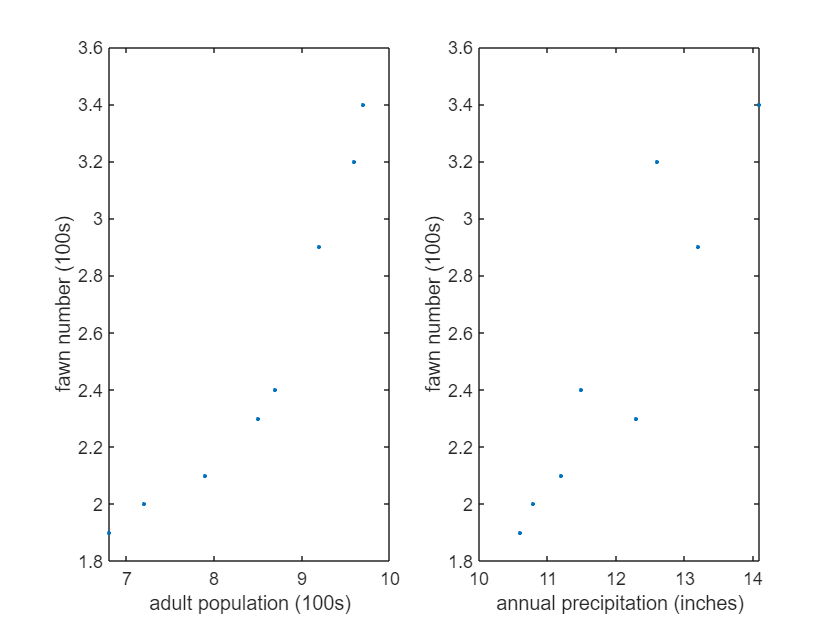

fawns = data.spring_fawn_count__hundreds_;
adults = data.adult_population__hundreds_;
precipitation = data.annual_precipitation__inches_;

clf
subplot(1,2,1)
plot(adults,fawns,'.')
xlabel('adult population (100s)') % x-axis label
ylabel('fawn number (100s)') % y-axis label

subplot(1,2,2)
plot(precipitation,fawns,'.')
xlabel('annual precipitation (inches)') % x-axis label
ylabel('fawn number (100s)') % y-axis label

corrcoef(adults, precipitation)

ans =     1.0000    0.9026
    0.9026    1.0000


m1 = fitlm(data,  'spring_fawn_count__hundreds_~adult_population__hundreds_+annual_precipitation__inches_')

m1 = Linear regression model:
    spring_fawn_count__hundreds_ ~ 1 + adult_population__hundreds_ + annual_precipitation__inches_

Estimated Coefficients:
                                     Estimate      SE        tStat      pValue 
                                     ________    _______    _______    ________

    (Intercept)                      -2.3155     0.75948    -3.0487    0.028465
    adult_population__hundreds_      0.29992     0.16241     1.8467     0.12407
    annual_precipitation__inches_    0.19158     0.14211     1.3481     0.23548


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 0.199
R-squared: 0.913,  Adjusted R-Squared: 0.878
F-statistic vs. constant model: 26.2, p-value = 0.00223

m2 = fitlm(data, 'spring_fawn_count__hundreds_~adult_population__hundreds_')

m2 = Linear regression model:
    spring_fawn_count__hundreds_ ~ 1 + adult_population__hundreds_

Estimated Coefficients:
                                   Estimate       SE        tStat       pValue  
                                   ________    ________    _______    __________

    (Intercept)                    -1.6791      0.63422    -2.6476      0.038152
    adult_population__hundreds_    0.49753     0.074529     6.6757    0.00054714


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.212
R-squared: 0.881,  Adjusted R-Squared: 0.862
F-statistic vs. constant model: 44.6, p-value = 0.000547

m3 = fitlm(data, 'spring_fawn_count__hundreds_~annual_precipitation__inches_')

m3 = Linear regression model:
    spring_fawn_count__hundreds_ ~ 1 + annual_precipitation__inches_

Estimated Coefficients:
                                     Estimate       SE        tStat      pValue  
                                     ________    ________    _______    _________

    (Intercept)                      -2.6325      0.87591    -3.0054      0.02384
    annual_precipitation__inches_    0.42845     0.072436     5.9149    0.0010394


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.236
R-squared: 0.854,  Adjusted R-Squared: 0.829
F-statistic vs. constant model: 35, p-value = 0.00104

m1.ModelCriterion

ans = struct with fields:
     AIC: -0.8889
    AICc: 5.1111
     BIC: -0.6506
    CAIC: 2.3494


m2.ModelCriterion

ans = struct with fields:
     AIC: -0.4086
    AICc: 1.9914
     BIC: -0.2498
    CAIC: 1.7502


m3.ModelCriterion

ans = struct with fields:
     AIC: 1.2714
    AICc: 3.6714
     BIC: 1.4303
    CAIC: 3.4303


***Blood pressure data***

This data ('blood_pressure.csv') looks at how peoples' systolic blood pressure depends on their age, weight and tea consumption (litres per day). Investigate whether age, weight or tea consumption have an effect on blood pressure. Please do not adjust your lifestyle based on this data, it is for illustration only ;-) .

***Exam scores data***

The data set on exam scores ('exam_scores.csv') is a hypothetical record of students' performance on a university module. It includes the results from three exams and the final exam. Your task is to investigate if any of the three exams predict students' performance in the final exam.

***Hollywood movie data***

The file 'hollywood_movies.csv' investigates revenues from book sales after the release of hollywood movies. Three possible predictors are included in the data: first year box office receipts, production costs and promotional costs. Investiate which out of these three variables predicts book sales.